# **PROJECT #2 **

**ENPM 667 : CONTROL OF ROBOTIC SYSTEMS**

**NAME : ADITYA VAISHAMPAYAN (116077354), ABHISHEK KATHPAL (114852373)**

**EMAIL ID: adityav@terpmail.umd.edu, akathpal@umd.edu**

**CONTACT NO: +1-240-743-0530; +1-240-667-6419**

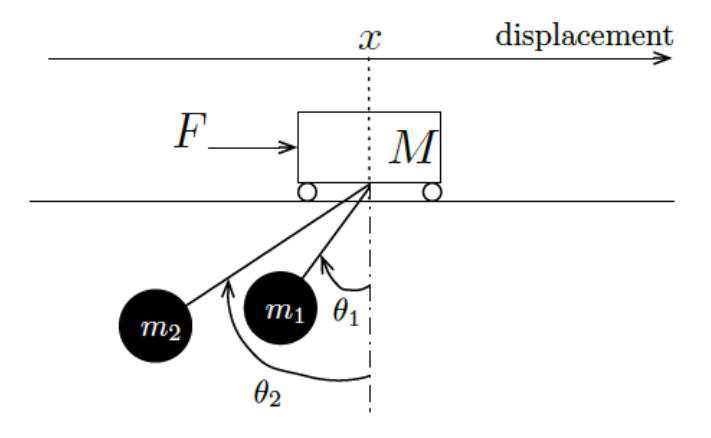

fig: Cart with two suspended loads moving in 1 dimensional direction 

## A) EQUATIONS OF MOTION 

*The equations of motion for this project are written in the report*

## B) LINEARIZING THE SYSTEM AROUND THE EQUILIBRIUM POINT AND OBTAINING THE STATE SPACE REPRESENTATION

*The system linearization is done using the samll angle approximation. The state space representation of the linearized system is given below*

syms M m1 m2 l1 l2 g;
A = [0  1      0            0       0           0;
     0  0   (-m1*g)/M       0   (-m2*g)/M       0;
     0  0      0            1       0           0;
     0  0   (-(m1+M)*g)/(M*l1)  0   (-m2*g)/(M*l1)  0;
     0  0      0            0       0           1;
     0  0   (-m1*g)/(M*l2)  0   (-(m2+M)*g)/(M*l2)  0]

$$A = \left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{g\,m_{1}}{M} & 0 & -\frac{g\,m_{2}}{M} & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{g\,\left(M+m_{1}\right)}{M\,l_{1}} & 0 & -\frac{g\,m_{2}}{M\,l_{1}} & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{g\,m_{1}}{M\,l_{2}} & 0 & -\frac{g\,\left(M+m_{2}\right)}{M\,l_{2}} & 0 \end{array}\right)$$

B = [0;
    (1/M);
     0;
    (1/(M*l1));
     0;
    (1/(M*l2))]

$$B = \left(\begin{array}{c} 0\\ \frac{1}{M}\\ 0\\ \frac{1}{M\,l_{1}}\\ 0\\ \frac{1}{M\,l_{2}} \end{array}\right)$$

C = eye(6);
D = [0;0;0;0;0;0];

## C) CONDITIONS FOR WHICH LINEARIZED SYSTEM IS CONTROLLABLE

We obtained the condition that $l_1 \not= l_2$. Hence if the given condition is followed then the system will become controllable

## D) LQR CONTROLLER

###         i) Initial Parameters

% Mass of the crane M
M = 1000; 
% Mass of the weight m1
m1 = 100;
% Mass of the weight m2
m2 = 100;
% Length of cable 1
l1 = 20;
% Length of cable 2
l2 = 10;
% gravity g
g = 9.8;

A = [0  1      0            0       0           0;
     0  0   (-m1*g)/M       0   (-m2*g)/M       0;
     0  0      0            1       0           0;
     0  0   (-(m1+M)*g)/(M*l1)  0   (-m2*g)/(M*l1)  0;
     0  0      0            0       0           1;
     0  0   (-m1*g)/(M*l2)  0   (-(m2+M)*g)/(M*l2)  0];
 
B = [0;
    (1/M);
     0;
    (1/(M*l1));
     0;
    (1/(M*l2))];

C = eye(6);

D = [0;0;0;0;0;0];

%eigen value of the open loop system. We can see that all the eigen values
%are imaginary. 
eig(A)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.7282i
   0.0000 - 0.7282i
   0.0000 + 1.0425i
   0.0000 - 1.0425i


###         ii) Q and R matrices of the LQR controller

% Q matrix is a 6x6 matrix. The diagonal elements of the Q matrix provides
% weights directly on the state variables wheres the non diagonal elements
% give weigts on the combinations of the of state variables
Q = eye(6);
Q(1,1) = 1000;
Q(2,2) = 1000;
Q(3,3) = 10000;
Q(4,4) = 10000000;
Q(5,5) = 10000;
Q(6,6) = 10000000;

% The R matrix is a 1x1 matrix in our case. It tells the system how much
% weight to put on the given input
R = 0.0001;

###         iii) Gain K obtained from the LQR controller

K = lqr(A,B,Q,R)

K = 	1.0e+04 *

    0.1000    0.5065    1.3467    9.7961    9.5599    2.2212


###         iv) State Feedback

%%Closed loop system
Ac = (A-B*K);
%Eigen values of the closed loop system after doing state feedback
eig(A-B*K)

ans =  -11.1328 + 0.0000i
  -0.4350 + 0.0000i
  -0.1815 + 0.3566i
  -0.1815 - 0.3566i
  -0.1269 + 0.7766i
  -0.1269 - 0.7766i


Bc = [0;0;0;0;0;0];
Cc = C;
Dc = 0;
% we obtain a closed loop system 
closed_loop_sys = ss(Ac,Bc,Cc,Dc);

% initial state of the system
X0 = [0;0;pi/20;0;pi/40;0];

% time for which we want the simulation to run
t = 0:0.01:70;
u = zeros(size(t));
[y,t,~] = lsim(closed_loop_sys,u,t,X0);

###         v) Plot of the cart position 

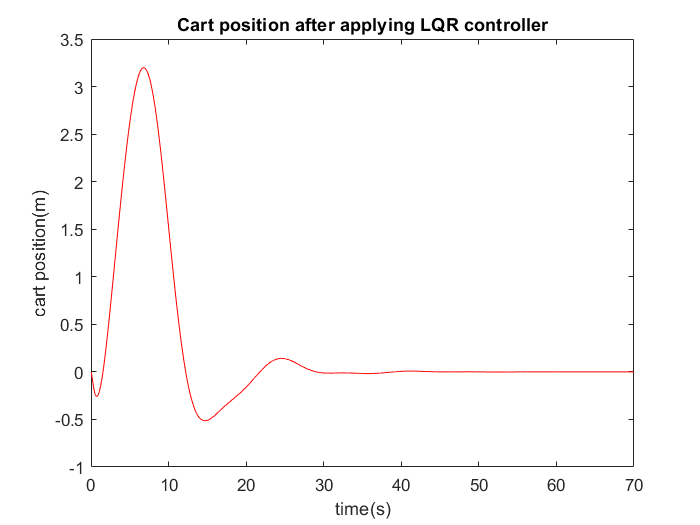

% here we write y(:,1) becuase we want to take the first state i.e. the
% position of the cart from the 6 available states
plot(t,y(:,1),'r');
title('Cart position after applying LQR controller');
xlabel('time(s)');
ylabel('cart position(m)');

###         vi) Plot of mass 1 angular position

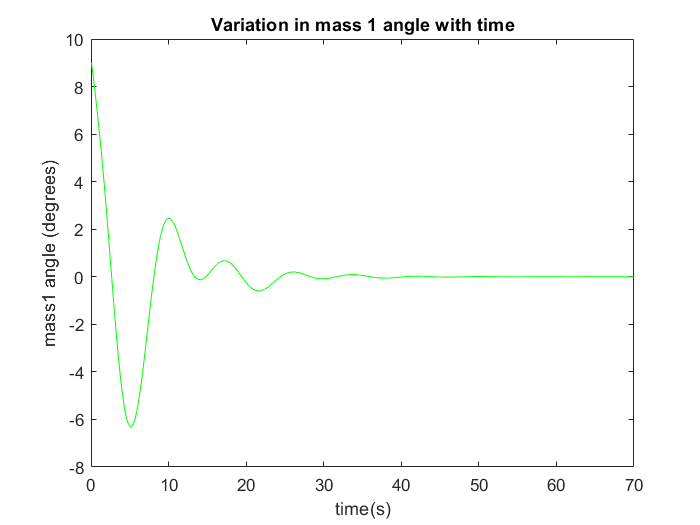

% here we have taken y(:,3) because we want to plot the third state i.e.
% theta 1 and we multiply it with 180/pi to convert radians to degree
plot(t,y(:,3)*180/pi,'g')
title('Variation in mass 1 angle with time');
xlabel('time(s)');
ylabel('mass1 angle (degrees)');

###         vii) Plot of mass 2 angular position

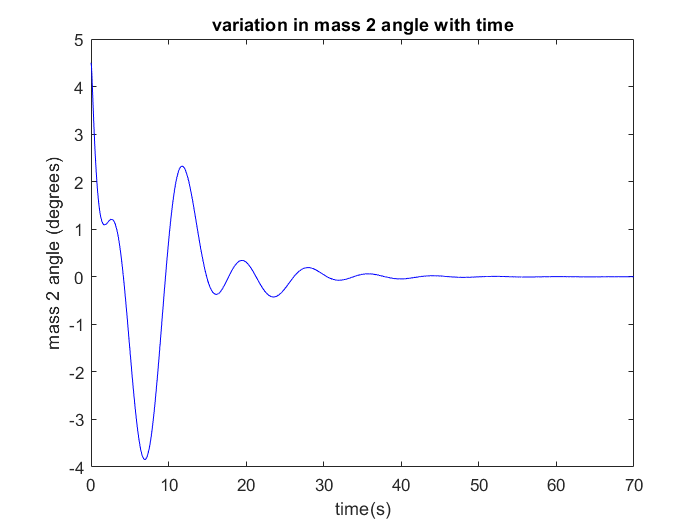

% here we have taken y(:,5) because we want to plot the fifth state i.e.
% theta 2 out of the six available states and we multiply it with 180/pi
% to convert radians to degree
plot(t,y(:,5)*180/pi,'b')
title('variation in mass 2 angle with time');
xlabel('time(s)');
ylabel('mass 2 angle (degrees)');

## E) DETERMINING OUTPUT VECTORS FOR WHICH THE SYSTEM IS OBSERVABLE

%linearized system is observable for x
C = [1 0 0 0 0 0];
rank(obsv(A,C))

ans = 6

%linearized system isn't observable for theta1 and theta2
C = [0 0 1 0 1 0];
rank(obsv(A,C))

ans = 4

%linearized system is observable for x and theta2
C = [1 0 0 0 1 0];
rank(obsv(A,C))

ans = 6


%linearized system is observable for x, theta1 and theta2
C = [1 0 0 0 1 0];
rank(obsv(A,C))

ans = 6

We can see from the **rank of observability matrices** that the pairs **x, x and theta_2, x theta_1 and theta_2 are observable** wheres the pair **theta_1 and theta_2 isn't observable.**


open('NonLinear_LQR.slx')